# Comparing Compression Techniques

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

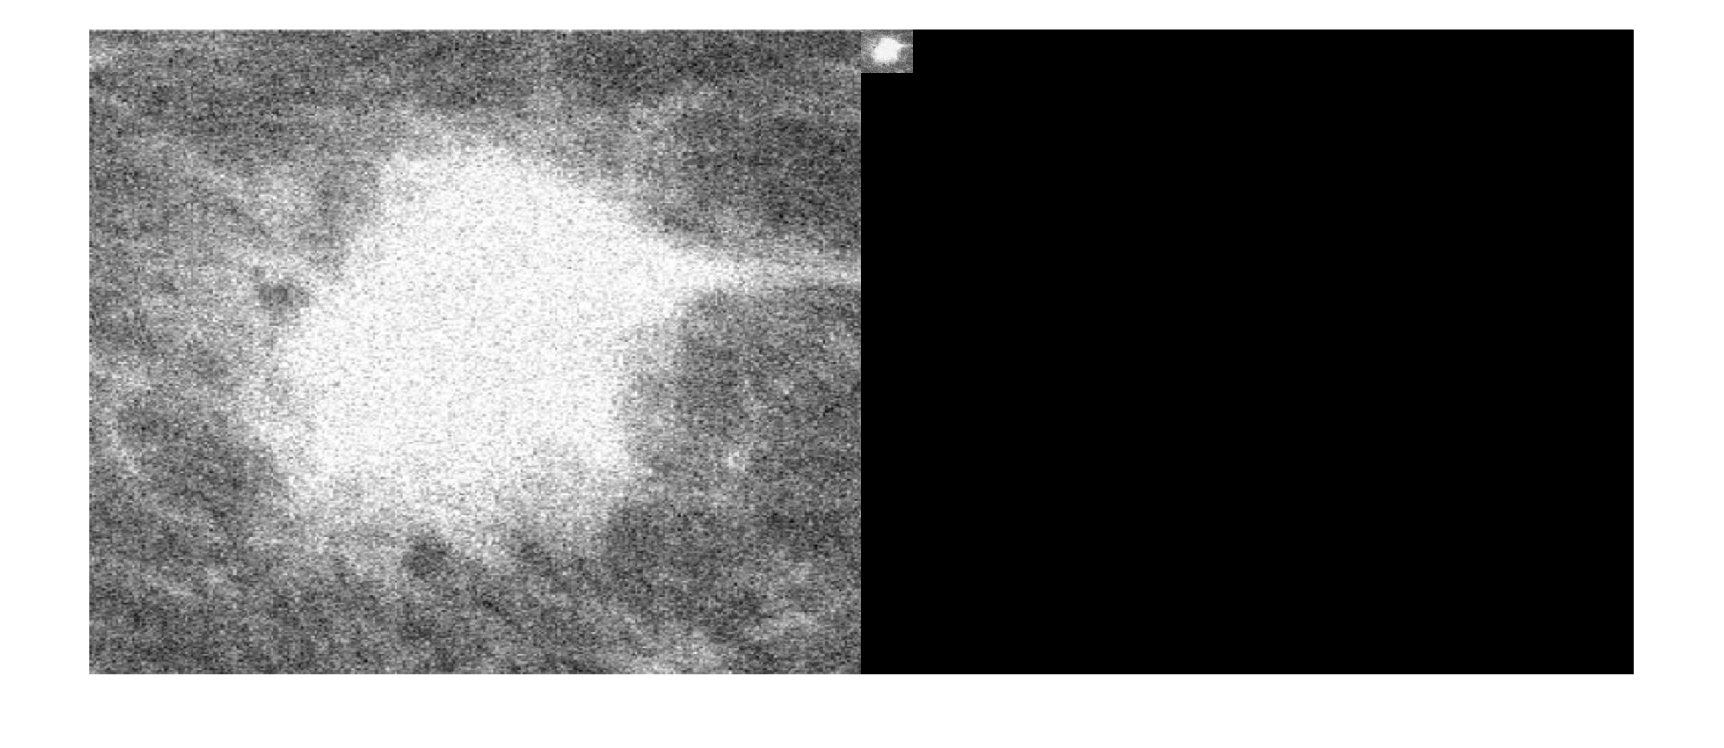

tumorRef = imread("./images/tumorLargeFile.jpg");  % original, large file
tumor = imread("./images/tumorReducedFile.jpg");  % image reduced wtih block processing
imshowpair(tumorRef, tumor, "montage")


szRef = size(tumorRef)

szRef =          965        1158


## Task 1

The variable `tumorRef` contains the original image. The variable `tumor` contains the image that was compressed with block processing.

You can use the `imresize` function to resize images to a specific size.

`imRSz` `=` `imresize``(``im``,``[``mRows` `nCols``])``;`

The second input is a 2-element vector specifying the size of the desired output.

tumorBP = imresize(tumor, szRef);

This code creates a comparison image that has been compressed and restored with the built-in function `imresize`.

szReduced = size(tumor);
tumorRS = imresize(tumorRef, szReduced);
tumorRS = imresize(tumorRS, szRef);

## Task 2

You are going to compare `tumorBP` to `tumorRS`, which was created in the script by using `imresize` to shrink and restore the image by the same amount.

The peak signal-to-noise ratio of an image with respect to a reference can be calculated with the `psnr` function.

`peaksnr` `=` `psnr``(``im``,``ref``)``;`

The higher the value, the better the quality.

peaksnrBP = psnr(tumorBP, tumorRef)

peaksnrBP = 21.6399

## Task 3

peaksnrRS = psnr(tumorRS, tumorRef)

peaksnrRS = 22.4597

## Task 4

PSNR looks only at intensity difference. There are other full-reference metrics that attempt to determine if qualities of the image are preserved. For instance, the structural similarity (SSIM) index can better reflect how well structures (e.g. edges and corners) are preserved. The SSIM index is between 0 and 1, with higher numbers representing better quality.

The `ssim` function takes the same inputs as the `psnr` function.

`ssimMetric` `=` `ssim``(``im``,``ref``)``;`

ssimBP = ssim(tumorBP, tumorRef)

ssimBP = 0.3123

ssimRS = ssim(tumorRS, tumorRef)

ssimRS = 0.3246